clc; clear; close all;
fprintf('=== WiDS Datathon 2021: Baseline MATLAB Solution ===\n\n');

=== WiDS Datathon 2021: Baseline MATLAB Solution ===




fprintf('Loading training and test data...\n');

Loading training and test data...



trainData = readtable('train.csv');
testData  = readtable('test.csv');

fprintf('Train shape: %d rows, %d columns\n', size(trainData,1), size(trainData,2));

Train shape: 130157 rows, 181 columns


fprintf('Test shape:  %d rows, %d columns\n', size(testData,1), size(testData,2));

Test shape:  10234 rows, 180 columns



% Identify target and ID columns
targetVar = 'diabetes_mellitus';   
idVar     = 'encounter_id';       

%% 2. Separate Predictors and Response
fprintf('Separating predictors and target variable...\n');

Separating predictors and target variable...


YTrain = trainData.(targetVar);
XTrain = removevars(trainData, {targetVar});

if any(strcmp(testData.Properties.VariableNames, idVar))
    testID = testData.(idVar);
else
    testID = (1:height(testData))'; % fallback
end

XTest = testData;

%% 3. Preprocessing: Handle Missing Values for Numeric & Text Data
fprintf('Starting data preprocessing (numeric + character handling)...\n');

Starting data preprocessing (numeric + character handling)...



datasets = {'XTrain', 'XTest'};

for d = 1:numel(datasets)
    T = eval(datasets{d});
    varNames = T.Properties.VariableNames;

    for i = 1:numel(varNames)
        col = T.(varNames{i});

        % Numeric Columns
        if isnumeric(col)
            meanVal = mean(col(~isnan(col) & ~isinf(col)));
            if isnan(meanVal) || isinf(meanVal)
                meanVal = 0;
            end
            col(isnan(col) | isinf(col)) = meanVal;
            T.(varNames{i}) = col;

        % Text or String Columns
        elseif iscellstr(col) || isstring(col)
            col = categorical(col);
            col(ismember(cellstr(col), {'NA', '', 'N/A', 'NaN'})) = missing;
            if any(ismissing(col))
                modeVal = mode(col(~ismissing(col)));
                col = fillmissing(col, 'constant', modeVal);
            end
            T.(varNames{i}) = double(categorical(col));

        % Already Categorical
        elseif iscategorical(col)
            if any(ismissing(col))
                modeVal = mode(col(~ismissing(col)));
                col = fillmissing(col, 'constant', modeVal);
            end
            T.(varNames{i}) = double(categorical(col));
        end
    end


    eval([datasets{d} ' = T;']);
end

fprintf('Preprocessing complete. Preview of first 5 rows (training data):\n');

Preprocessing complete. Preview of first 5 rows (training data):


disp(head(XTrain, 5));

    Var1    encounter_id    hospital_id    age     bmi      elective_surgery    ethnicity    gender    height    hospital_admit_source    icu_admit_source    icu_id    icu_stay_type    icu_type    pre_icu_los_days    readmission_status    weight    albumin_apache    apache_2_diagnosis    apache_3j_diagnosis    apache_post_operative    arf_apache    bilirubin_apache    bun_apache    creatinine_apache    fio2_apache    gcs_eyes_apache    gcs_motor_apache    gcs_unable_apache    gcs_verbal_apache<

fprintf('\n');

%% 4. Train/Validation Split
fprintf('Splitting training data (80/20) for internal validation...\n');

Splitting training data (80/20) for internal validation...


cv = cvpartition(YTrain, 'HoldOut', 0.2);
idxTrain = training(cv);
idxVal   = test(cv);

Xtr = XTrain(idxTrain, :);
Ytr = YTrain(idxTrain);
Xval = XTrain(idxVal, :);
Yval = YTrain(idxVal);

fprintf('Split complete: %d train, %d validation samples.\n\n', sum(idxTrain), sum(idxVal));

Split complete: 104126 train, 26031 validation samples.




fprintf('Generating correlation heatmap of features...\n');

Generating correlation heatmap of features...


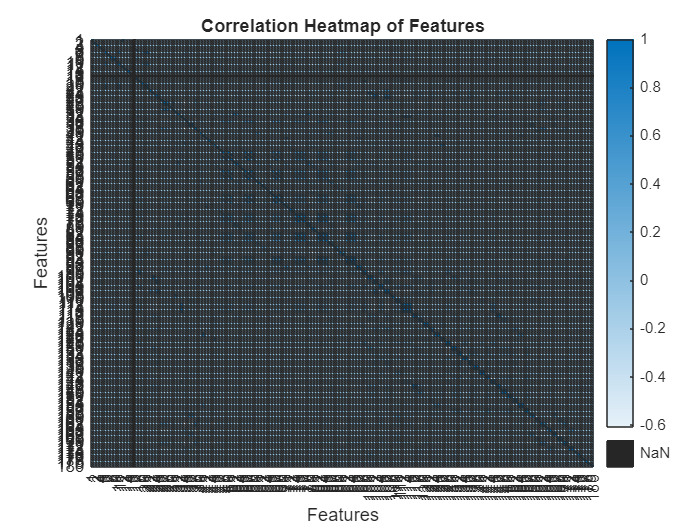

figure;
heatmap(corr(table2array(XTrain), 'Rows', 'pairwise'));
title('Correlation Heatmap of Features');
xlabel('Features');
ylabel('Features');


%% 5. Train Decision Tree
fprintf('Training Decision Tree classifier...\n');

Training Decision Tree classifier...


Mdl = fitctree(Xtr, Ytr, 'MinLeafSize', 5, 'Surrogate', 'on');
fprintf('Model training complete.\n\n');

Model training complete.




%% 6. Validate Model
fprintf('Evaluating model on validation data (with probabilities)...\n');

Evaluating model on validation data (with probabilities)...


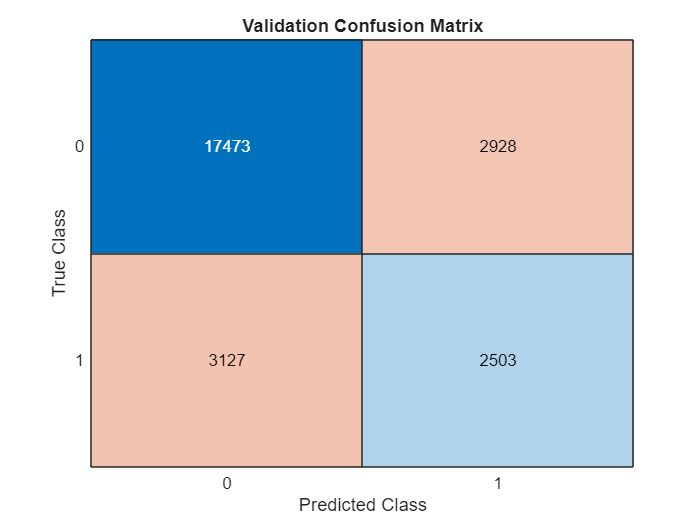

[YPredVal, scoresVal] = predict(Mdl, Xval);

figure;
confusionchart(Yval, YPredVal);
title('Validation Confusion Matrix');


valAccuracy = sum(YPredVal == Yval) / numel(Yval);
fprintf('Validation Accuracy: %.2f%%\n', valAccuracy*100);

Validation Accuracy: 76.74%


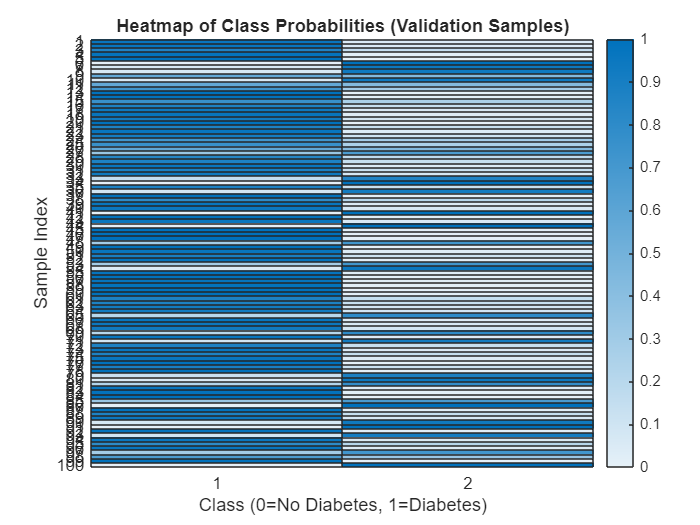


% Probability Heatmap
figure;
heatmap(scoresVal(1:100,:)); % first 100 samples
title('Heatmap of Class Probabilities (Validation Samples)');
xlabel('Class (0=No Diabetes, 1=Diabetes)');
ylabel('Sample Index');

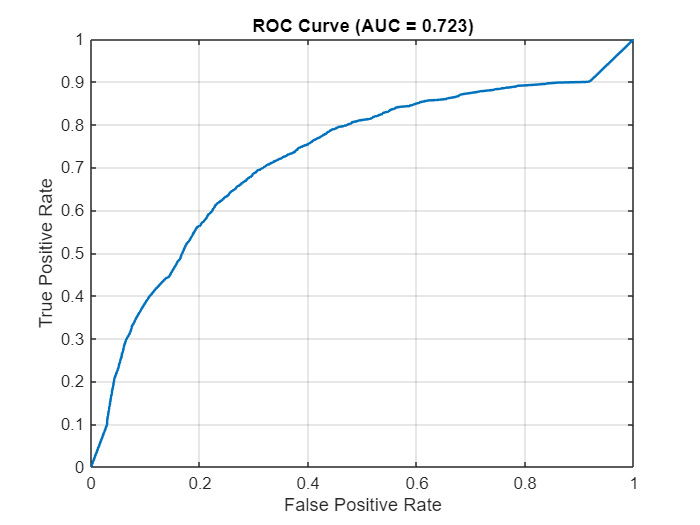


% ROC & AUC
[Xroc, Yroc, Troc, AUC] = perfcurve(Yval, scoresVal(:,2), 1);
figure;
plot(Xroc, Yroc, 'LineWidth', 1.5);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ' num2str(AUC, '%.3f') ')']);
grid on;

fprintf('Validation AUC: %.3f\n\n', AUC);

Validation AUC: 0.723




%% 7. Train Final Model on Full Training Data
fprintf('Retraining on full dataset for final submission...\n');

Retraining on full dataset for final submission...


FinalMdl = fitctree(XTrain, YTrain, 'MinLeafSize', 5, 'Surrogate', 'on');
fprintf('Final model trained.\n\n');

Final model trained.




%% 8. Predict on Test Data (with Probabilities)
fprintf('Predicting on test set with probabilities...\n');

Predicting on test set with probabilities...


[YPredTest, scoresTest] = predict(FinalMdl, XTest);
prob_diabetes = scoresTest(:,2); % Probability of class 1 (diabetes)

%% 9. Save Submission File
fprintf('Saving predictions to submission.csv...\n');

Saving predictions to submission.csv...


submission = table(testID, YPredTest, prob_diabetes, ...
    'VariableNames', {idVar, [targetVar '_class'], [targetVar '_probability']});
writetable(submission, 'submission.csv');
fprintf('Submission file "submission.csv" created successfully!\n\n');

Submission file "submission.csv" created successfully!




fprintf('=== DONE: WiDS Datathon 2021 Baseline MATLAB Solution (with Probabilities + Heatmap) ===\n');

=== DONE: WiDS Datathon 2021 Baseline MATLAB Solution (with Probabilities + Heatmap) ===
